## Tandbredde (Tandopgve7)

### Opgave

Et ligfortandet tandhjulspar består af:

- Tandantal $N_1 = 20$ og $N_2 = 40$

- Moment Tandhjul 1: $T_1 = 40 Nm$

- 
$$n_1 = 3000 rpm$$


- Modul: $2 mm$

- Indgrebsvinkel $20^\circ$

- Kvalitetstal $Q_v = 5$.

Bestem tandbredden (den samme for begge hjul) tandfodsspændinger for tandhjulene er $100 MPa$.

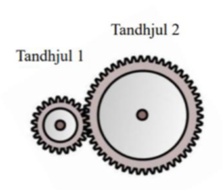

Vi ved at bøjningsspændingen i tandfoden er $\sigma_{max} = 100 MPa$ og den er givet som

$\sigma_{\max } =\frac{\;W^t \cdot K_v \cdot K_{\epsilon \;} \cdot K_F }{\;b\cdot m}$ => $b=\frac{\;W^t \cdot K_v \cdot K_{\epsilon \;} \cdot K_F }{\;\sigma_{\max } \cdot m}$

Vi får derved to påkrævede $b$ værdier, én for hver $K_F$, den begrænsende er den maksimale:


$$b_{\mathrm{req}} =\frac{\;W^t \cdot \max \left(K_{\mathrm{F1}} ,K_{\mathrm{F2}} \right)\cdot K_{\epsilon \;} \cdot K_v }{\;\sigma_{\max } \cdot m}$$


%Givne størrelser
N_1 = 20;
N_2 = 40;
T_1 = 40;
n_1 = 3000;
m = 0.002;
alpha_deg = 20;
Q_v = 5;
sigma_max = 100e6;

%Formfaktorer
K_F1 = 2.2 + 3.1 * exp(-N_1/14);
K_F2 = 2.2 + 3.1 * exp(-N_2/14);

%Indgrebsfaktor
m_c = indgrebsgrad(m, N_1, N_2, alpha_deg);
K_ep = 1/m_c;

%Tangentialkraft
W_t = T_1/(d_1/2);

%---Dynamisk faktor---
B = 0.25 * (12-Q_v)^(2/3);
A = 50 + 56 * (1 - B);

%Delecirkeldiameter
d_1 = N_1 * m;

%Hastighed
omega_1 = n_1 * 2 * pi/60;
V = d_1/2 * omega_1;

%Dynamisk faktor
K_v = ((A + sqrt(200 * V))/A)^B;

%---Udregning---
b_req = (W_t * max(K_F1, K_F2) * K_ep * K_v)/(sigma_max * m);
b_reqmm = b_req * 1000;

fprintf("Den mindste tandbredde der overholder kravene\ner på %.5f m = %.2f mm", b_req, b_reqmm);

Den mindste tandbredde der overholder kravene
er på 0.02841 m = 28.41 mm